# A GUIDE to Basic Singular Spectrum Analysis Class

## Introduction

Singular Spectrum Analysis (SSA) is a non-parametric technique of time series analysis and forecasting. SSA aims at decomposing the original series in a small number of possibly interpretable components such as a slowly varying trend, oscillatory components, and noise.

This documentation describes the `ssaBasic` class which implements the Singular Spectrum Analysis (SSA) according to the book "Analysis of Time Series Structure: SSA and Related Techniques" by N. Golyandina, V. Nekrutkin, and A. Zhigljavsky, 2001.

## Methods of the class `ssaBasic`

### 1. CONSTRUCTOR: ssaBasic`(data, L0)`

Initializes the `ssaBasic` class with the original time series `data` and the number of Lags `L0 `(or window length).

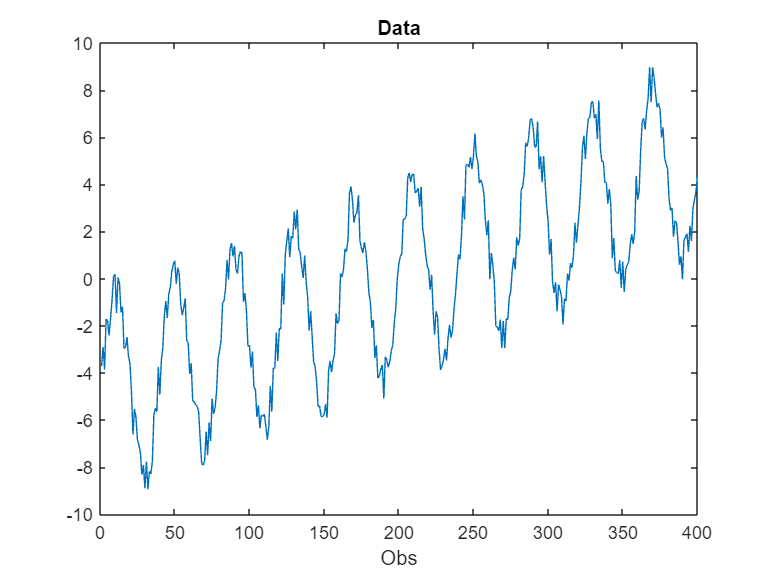

% Initialize SSA with data and L0 (number of lags or window length)
N = 400;
t = (1:N) - floor(N/2);
data = t/40 + 4*sin(2*pi*t/40) + 2*(rand(1,N)-0.5);
L0 = floor(N/2);
mySSA = ssaBasic(data,L0);
% plot
plot(data)
title('Data')
xlabel('Obs')

### 2. `ssaBasic.plotSingularValues(numValues, display)`

The method `plotSingularValues` visualizes the singular values and their contribution to the overall signal variance, helping to interpret the importance of each component in Singular Spectrum Analysis. The method produces one or two types of plots depending on the value of the `display` parameter. The scree plot shows the first `numValues` singular values in descending order, highlighting the most significant components. The cumulative contribution plot is a bar chart that displays the relative cumulative contribution of each singular value to the total variance in the signal.

The method takes two parameters. The first parameter, `numValues`, specifies the number of singular values to display in the plots. The second parameter, `display`, determines which plot or plots are generated. If `display` is set to `'double' `(default), both the scree plot and the cumulative contribution plot are produced. If `display` is set to `'scree'`, only the scree plot is created, while setting it to `'cm'` generates only the cumulative contribution plot.

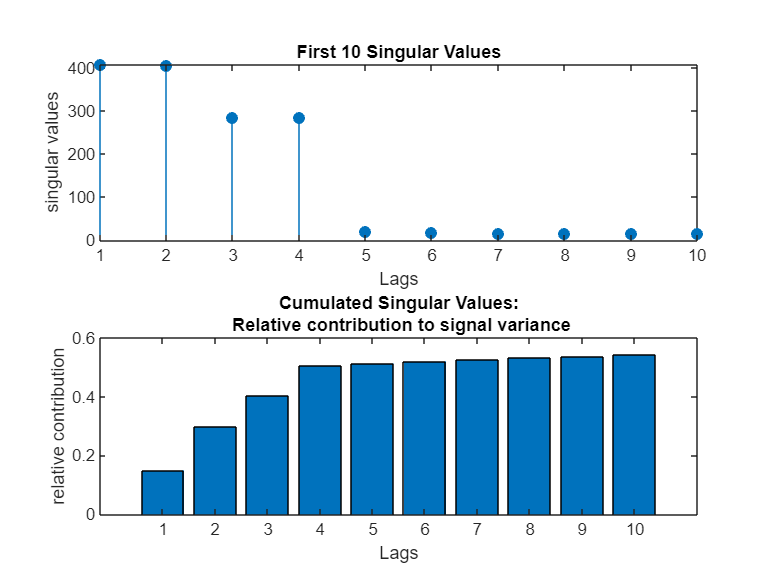

% Plot the first 10 singular values and their contribution
numValues = 10;
mySSA.plotSingularValues(numValues,'double')

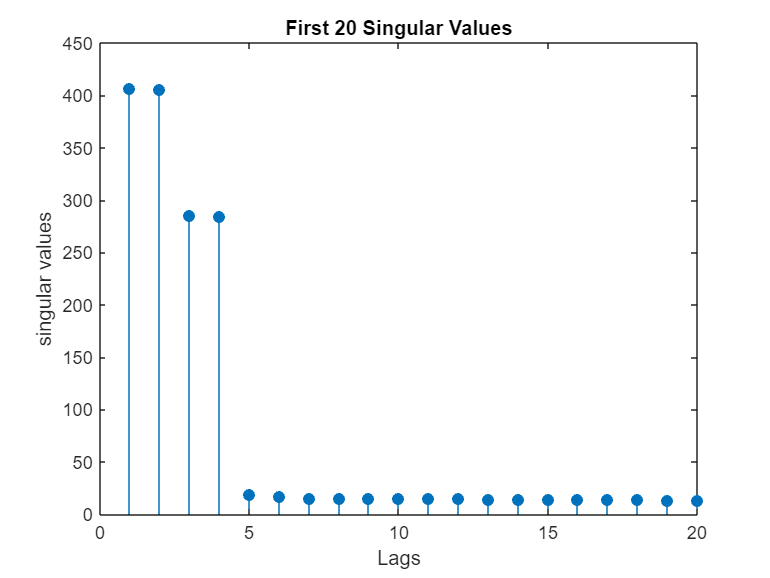

% Scree plot of the first 20 singular values
mySSA.plotSingularValues(20,'scree');

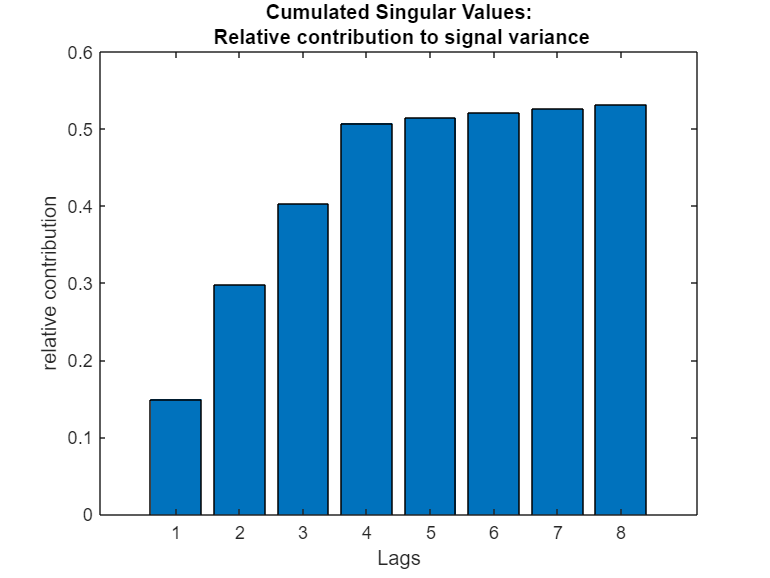

% Cumulative contribution plot for the first 8 singular values
mySSA.plotSingularValues(8,'cm');

### 3. `C = ssaBasic.wcorrelation(Group, display)`

The method `wcorrelation `assesses how separated are the eigen-triples (groups), according to the clusters specified in the array `Group`. In particular, the weighted correlation matrix quantifies the (weighted) correlation between these latter components. By default, this method draws the weighted correlation matrix for visual analysis. However, if the `display` parameter is set to any string other than `'on'`, the matrix will not be plotted.

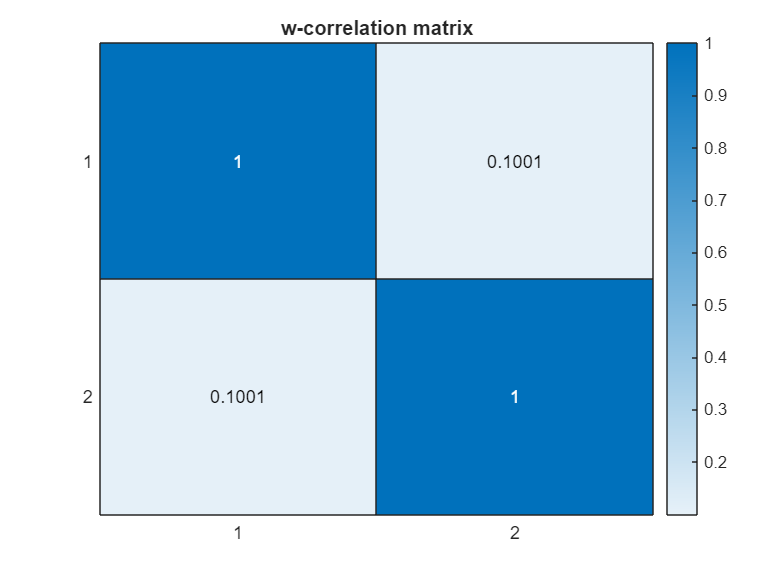

% Compute the weighted correlation matrix and plot it 
Group = [1 1 2 2];
wcorMatrix = mySSA.wcorrelation(Group);

% Compute the weighted correlation matrix without displaying the plot
wcorMatrix = mySSA.wcorrelation(Group,'off');

### 4. `ssaBasic.scatterplotseigEnvectors(Group)`

The method `scatterplotEigenvectors` visualizes the periodicity of the principal components (eigen-triples) obtained through Singular Spectrum Analysis, according to the specified grouping in the variable `Group`. This method generates scatter plots of paired eigenvectors. If a component corresponds to an odd number of eigen-triples, the scatter plot will be empty, indicating no clear periodicity.

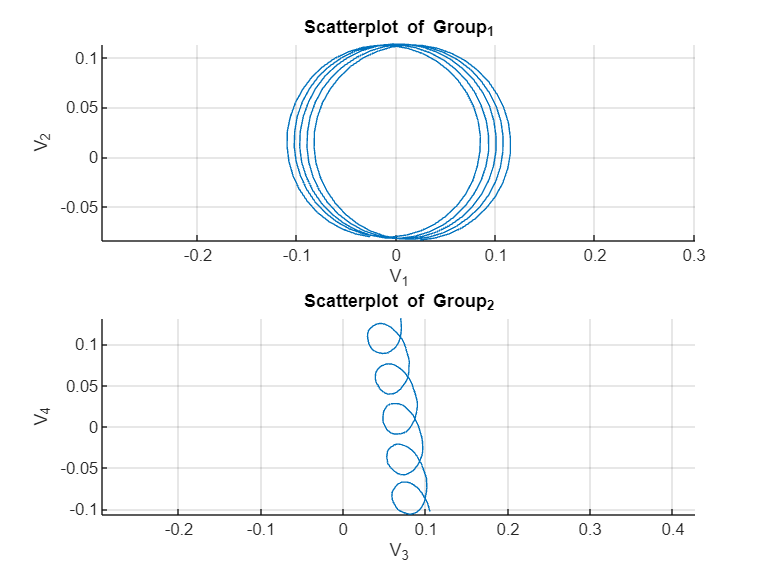

% Create scatter plots of eigenvectors to analyze periodicity
Group = [1 1 2 2];
mySSA.scatterplotsEigenvectors(Group);

Component 2 corresponds to 3 singular vectors; scatter plot not possible.


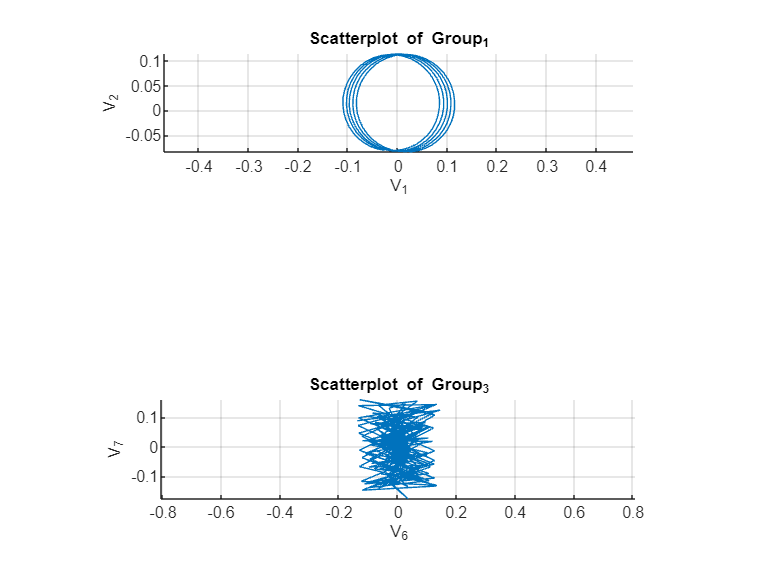

% For components that have an odd number of eigen-triples,
% the scatter plot will be empty, indicating no clear periodicity.
GroupOdd = [1 1 2 2 2 3 3];
mySSA.scatterplotsEigenvectors(GroupOdd);

### 5. `[best_L0, best_rmse] = ssaBasic.crossval_L0(r_prior, qInSample, numTest, display)`

Given an "a priori" assessment of relevant leading singular values (`r0`), the method `crossval_L0` automatically tunes the number of Lags (`L0)`. This method takes three input parameters: `r0`, which is the number of leading singular values suggested by the scree plot; `qInSample `(optional), which represents the proportion of the sample used for cross-validation (default value is set to 0.9 if not provided); and `numTest `(optional), the number of trials for cross-validation (default value is set to 100 if not provided). The method returns `best_L0`, the optimal number of Lags, and `best_rmse`, the corresponding Root Mean Squared Error (RMSE) value, which is the total of both in-sample and out-of-sample errors. By default, the method will plot the results of the cross-validation, but if you wish to suppress the plot, you can pass a `display` parameter with a value other than `'on'`. 

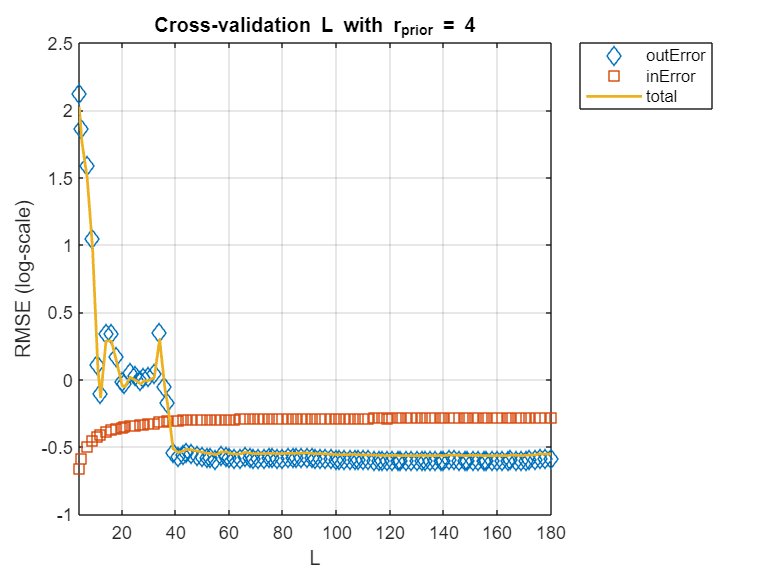

% Set a prior for r0
r0 = 4;
% Run cross-validation to find the best L0 with default parameters
[best_L0, best_rmse] = mySSA.crossval_L0(r0);

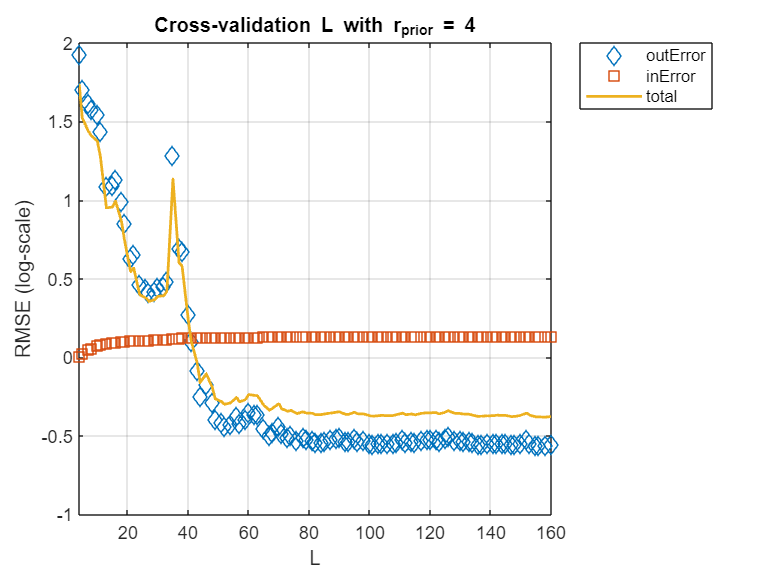

% Run cross-validation with a custom proportion for cross-validation and number of trials
[best_L0, best_rmse] = mySSA.crossval_L0(r0, 0.8, 50);

% Run cross-validation without displaying the plot
[best_L0, best_rmse] = mySSA.crossval_L0(r0, 0.8, 50, 'off'); 

### 6. `[best_r0, best_rmse] = ssaBasic.crossval_r0(qInSample, numTest, display)`

The method `crossval_r0` automatically tunes the number of relevant singular values (`r0`) given the number of lags `L0`. This method takes several input parameters: `qInSample `(optional), which represents the proportion of the sample used for cross-validation (default value is set to 0.9 if not provided); and `numTest `(optional), the number of trials for cross-validation (default value is set to 100 if not provided). The method returns `best_r0`, the optimal number of eigen-triples (r), and `best_rmse`, the corresponding Root Mean Squared Error (RMSE) value, which is the total of both in-sample and out-of-sample errors. By default, the method will plot the results of the cross-validation, but if you wish to suppress the plot, you can pass a `display` parameter with a value other than `'on'`. 

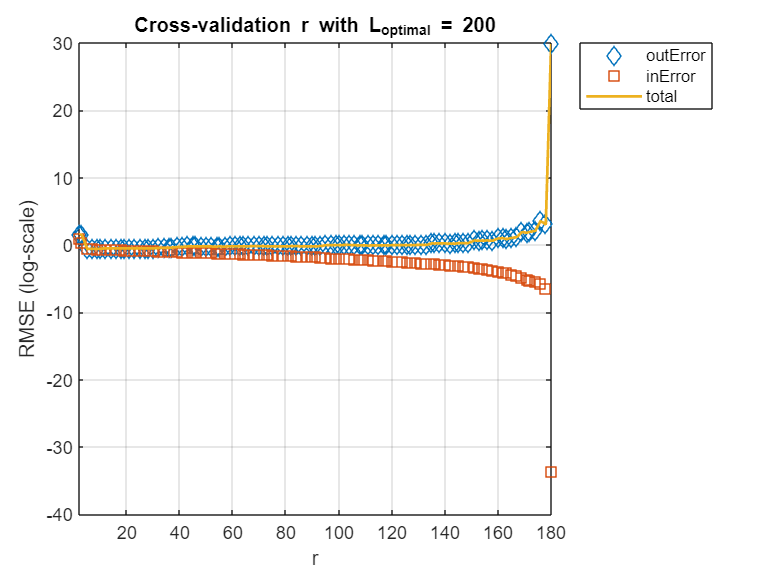

% Run cross-validation to find the best r0 with default parameters
[best_r0, best_rmse] = mySSA.crossval_r0();

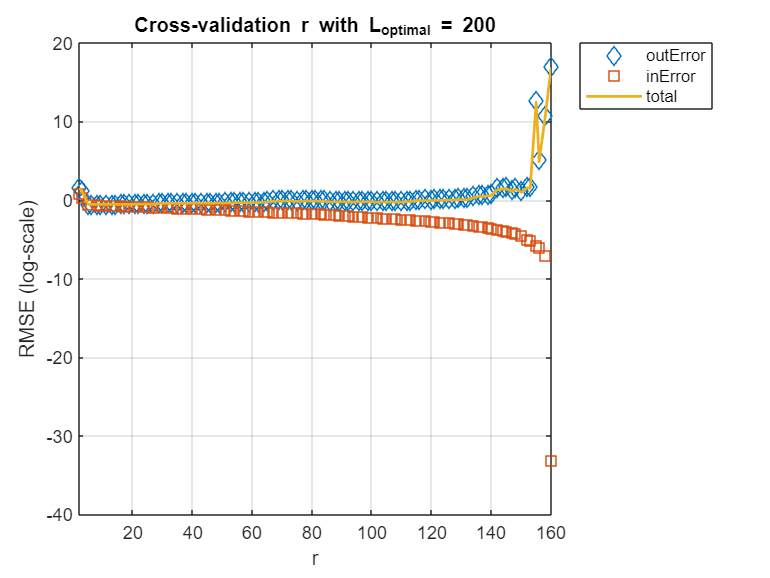

% Run cross-validation with a custom proportion for cross-validation and number of trials
[best_r0, best_rmse] = mySSA.crossval_r0(0.8, 50);

% Run cross-validation without displaying the plot
[best_r0, best_rmse] = mySSA.crossval_r0(0.8, 50, 'off');

### 7. `[testRMSE, xF] = ssaBasic.backtest(r0,qInSample,redNoiseMdl)`

The method `backtest` evaluates the robustness of the SSA forecasts by splitting the data sample into two sets: an in-sample set and an out-of-sample set. It performs the calibration using the SSA method on the in-sample data and then compares the forecast computed according to the Linear Recursion Formula (LRF) with the actual data from the out-of-sample set. This method helps assessing how well the model matches real data. Optionally, if an explicit model of the residual or noise component is provided by the `redNoiseMdl` variable, `backtest` compares RMSE of the focast of the combination of SSA + redNoiseMdl, to the RMSE of the forecast performed by SSA.

The method takes several inputs. The first input is `r0`, which specifies the number of eigen-triples to use for reconstruction and forecasting with SSA. The second input is `qInSample `(optional), which is a array indicating the proportion of data to be used as the in-sample set for the backtesting (e.g. `[0.8, 0.7])`. Eventually, the `redNoiseMdl `provides an explicit model of the noise component if autocorrelation is detected in the model residuals. `redNoiseModel` can be a MATLAB `arima` model specification or a user defined model with the methods 'estimate' and 'forecast' implemented.

The method returns two outputs. The first output is `testRMSE`, a matrix containing the RMSE values for each in-sample proportion. The first column of `testRMSE` contains the RMSE values of the SSA only forecasts, while the second column contains the RMSE values for the combined SSA and residual noise forecast if `redNoiseMdl` is provided. If no red noise model is supplied, the second column will contain a vector of zeros. The second output is `xF`, a matrix of forecasts. The first column of `xF` contains the SSA forecasts. If `redNoiseMdl` is provided, the second column will contain the forecasts from combining SSA and the noise model. If no red noise model is provided, this column will contain an array of zeros.

r0 = 4;
% Run the backtest for SSA with r = 4, using 70% and 80% of the data as in-sample
[testRMSE, xF] = mySSA.backtest(r0, [0.9, 0.8]); 

% Define a red noise model (assuming redNoiseMdl is a valid object with 'estimate' and 'forecast' methods)
redNoiseMdl = arima('Constant',0,'ARLags',1); % autoregressive model
[testRMSE_NoiseMdl, xF_NoiseMdl] = mySSA.backtest(r0, [0.9, 0.8], redNoiseMdl);

The model "arima" has the "estimate" and "forecast" methods.


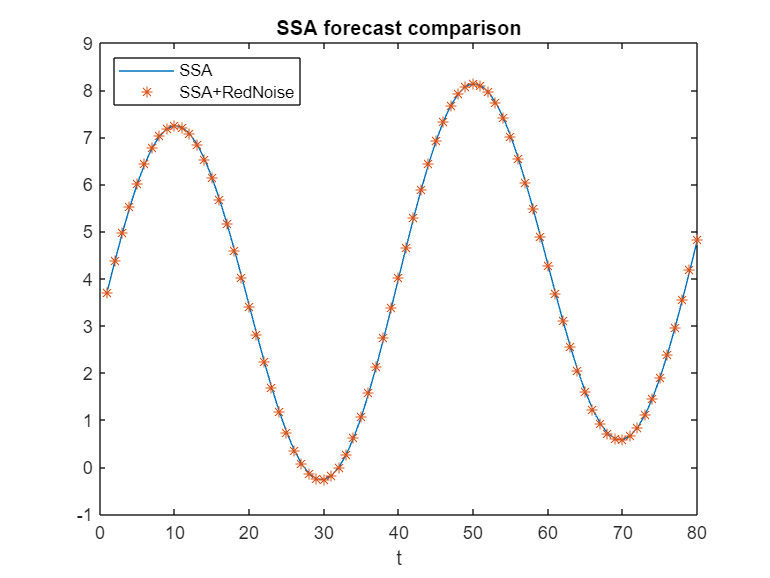

figure
t = 1:length(xF_NoiseMdl(:,1));
plot(t,xF_NoiseMdl(:,1),'-',t,xF_NoiseMdl(:,2),'*')
title('SSA forecast comparison')
xlabel('t')
legend({'SSA','SSA+RedNoise'},'Location','northwest')

### 8. `y = ssaBasic.reconstruction(r0)`

The method `reconstruction` reconstructs the signal from its trajectory matrix using Singular Value Decomposition (SVD). The reconstruction is based on the `r0` leading singular value.

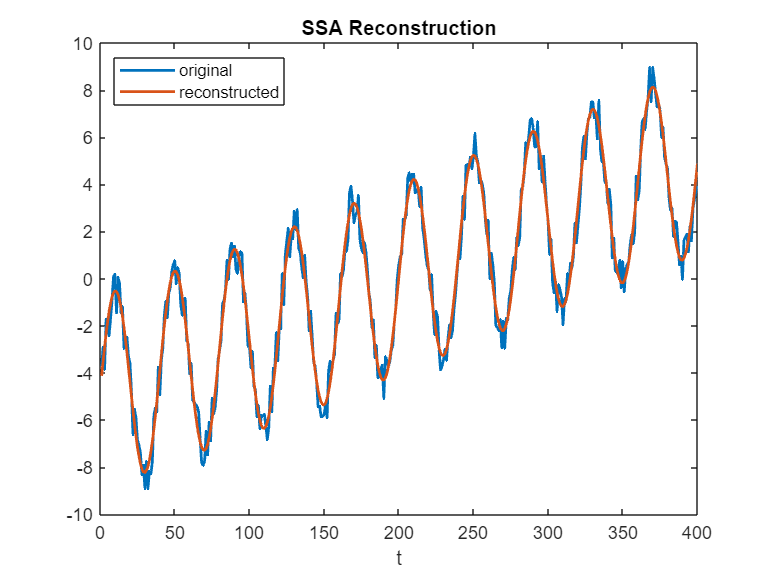

% Reconstruct the signal using the first 4 leading singular values
r0 = 4;
reconstructedSignal = mySSA.reconstruction(r0);
% plot true vs reconstructed signal
t = 1:length(data);
plot(t,data,t,reconstructedSignal,'LineWidth',1.5)
title('SSA Reconstruction')
legend('original','reconstructed','Location','northwest')
xlabel('t')

### 9. `y = ssaBasic.grouping(Group, display)`

The method `grouping` groups eigen-triples according to the variable `Group,` which is a specified grouping array. The `Group` array consists of a series of numbers that indicate how the eigen-triples should be grouped. For example, in case `Group = [1 1 2 2]`, the first two and the third and fourth eigen-triples will form two separate groups. This method helps to combine similar components, facilitating the interpretation of the signal structure. The variable `display `(optional), controls whether the grouped components are plotted. If `display` is set to any string other than `'on'`, no plot will be generated.

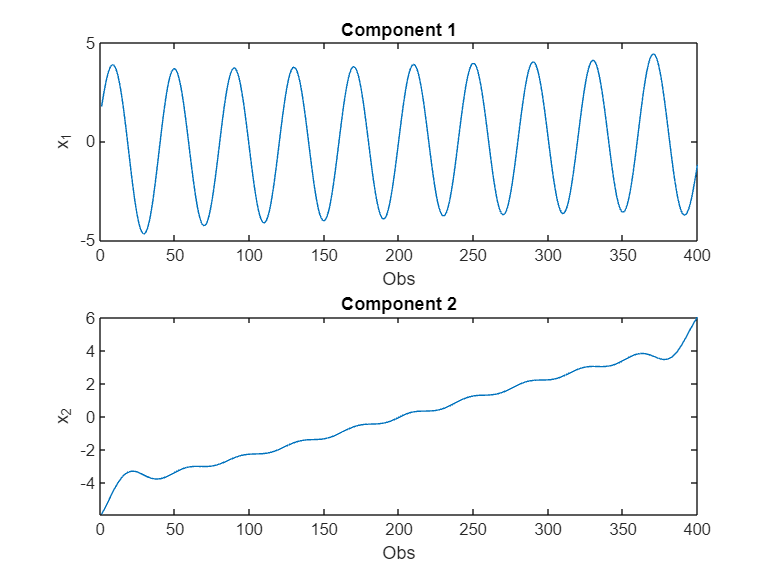

% Group eigen-triples based on the array G = [1 1 2 2]
groupedComponents = mySSA.grouping([1 1 2 2]); %#ok<*NASGU>

% Group eigen-triples and suppress the plot
groupedComponents = mySSA.grouping([1 1 2 2], 'off');

### **10. **`[xM, xCi, xSamp] = ssaBasic.forecast(r0, M, numSamp, display)`

The method forecast reconstructs and forecasts the signal from its trajectory matrix for the number of periods specified in `M`. If `r0 `is a scalar, the method uses the first `r0` singular values for the reconstruction. If `r0` is an array, the method uses the singular values corresponding to the indices listed in `r0`. For example, if `r = [1, 2, 5]`, it will use the 1st, 2nd, and 5th singular values for the reconstruction and forecast. An optional input, `numSamp`, defines the number of bootstrap samples to generate for confidence bands estimation, with a default value of 100 if not specified. Another optional input, `display`, controls whether a fan plot of the forecast is shown. If set to `'on'`, the plot will be displayed; if set to `'off'` (the default), no plot will be shown. The first part of the graph reports the last 10% of the sample.

The output consists of three variables. The first output, `xM`, is a vector containing the original time series data followed by the forecasted values for the next `M` periods. The second output, `xCi`, is a matrix containing the confidence intervals for the forecasted values, calculated by the `bootstrap` method, with intervals corresponding to the 97.5th and 2.5th percentiles. The third output, `xSamp`, is a matrix containing the forecast values derived from the bootstrap samples, where each row represents a different bootstrap sample forecast.

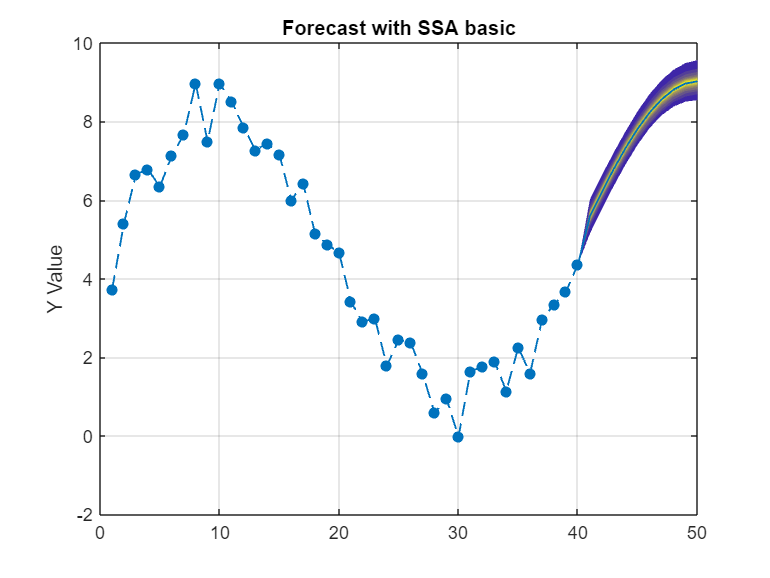

% Reconstruct the signal using the first 4 singular values and forecast 10 periods ahead
r0 = 4;
M = 10;
[xM, xCi, xSamp] = mySSA.forecast(r0,M); %#ok<*ASGLU>
% Reconstruct the signal using the 1st, 2nd, and 4th singular values and forecast 10 periods ahead
[xM, xCi, xSamp] = mySSA.forecast([1, 2, 4], M);
% Reconstruct the signal, forecast 10 periods ahead, generate 200 bootstrap samples, and display the fan plot
[xM, xCi, xSamp] = mySSA.forecast(r0, M, 200, 'on');

% Reconstruct the signal, forecast 10 periods ahead, and suppress the fan plot
[xM, xCi, xSamp] = mySSA.forecast(4, 10, 200, 'off');